# SVD

## Intro

### Definition and uses

#### Uses:

**Solve lin system.**

Ax = b, nonsquare A

Takes highly complex data, and distills it, to eigenvectors.

#### Definition

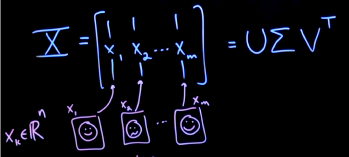

Will decompose a matrix into 3 others.

U, orthogonal, sigma, diagonal, and 

Both U, and V are unitary, meaning that they are all columns are orthogonal, and have a unit length. And can completely represent R_n.

So its transpose is its inverse.

The eigenvalues in U, are in decreasing importance towards representing the data X. 

Therefore the sigma values are in nonincreasing order. And sigma_1 is therefore the largest.

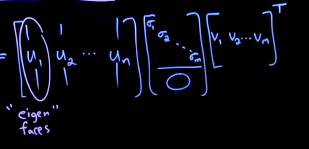

V tells you the exact mixture of eigenfaces that would represent each specific face.But v1, represents the use of u1, in each consecutive face.

The first column of them all represent the combination of the U vectors.

### Computation

Given some data matrix, X.

In our example we take faces shaped into n sized vectors.

m = 4;
n = 10;
X = randi(10, n, m);
[U, sigma, V] = svd(X);
size(V)

ans =      4     4


disp(X)

     3     6     4     9
     1     2     6     5
     8     9     9     6
     1     7     1     2
     7     9     6     7
     5     8     5    10
     3     9    10     6
     7     7     7     5
     4     8    10     8
     2     7     6     1



disp(U)

   -0.2826   -0.5395   -0.0428    0.1855   -0.3478   -0.6149    0.0002   -0.1356   -0.1775    0.2095
   -0.1824   -0.0950   -0.5703   -0.0620    0.2857    0.0372   -0.5056    0.2314   -0.4452   -0.1955
   -0.4026    0.2333    0.1721   -0.4144   -0.3008    0.1269   -0.1900   -0.5832   -0.2170   -0.2285
   -0.1513    0.0698    0.4496    0.6166   -0.0667   -0.0103   -0.3141    0.1595    0.0057   -0.5111
   -0.3654   -0.0785    0.3682   -0.1619    0.7841   -0.2571    0.0792   -0.0796    0.0432    0.0558
   -0.3564   -0.5159    0.1283    0.0877   -0.0375    0.7192    0.0830    0.0886   -0.0294    0.2204
   -0.3709    0.2866   -0.3168    0.3021    0.0284    0.0164    0.7000   -0.0088   -0.2354   -0.2049
   -0.3243    0.1462    0.1816   -0.4352   -0.2910   -0.1404    0.0704    0.7345    0.0427   -0.0221
   -0.3901    0.0342   -0.3919    0.0621   -0.0216   -0.0252   -0.1718   -0.0908    0.8042   -0.0601
   -0.2156    0.5135    0.0468    0.3023   -0.0161    0.0203   -0.2682    0.0222   -0.1284 

disp(U * sigma) % represents economy U, the only needed ones.

  -11.1630   -4.0433   -0.2752    0.9816
   -7.2055   -0.7118   -3.6697   -0.3282
  -15.9031    1.7483    1.1076   -2.1928
   -5.9759    0.5233    2.8928    3.2628
  -14.4328   -0.5886    2.3694   -0.8568
  -14.0767   -3.8664    0.8254    0.4641
  -14.6517    2.1485   -2.0387    1.5987
  -12.8114    1.0960    1.1684   -2.3027
  -15.4099    0.2566   -2.5219    0.3288
   -8.5169    3.8487    0.3008    1.5996



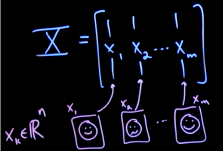

**Some things to know:**

Because n is way larger than m, only the first n U vectors are important to representing X.

The final representation of X is such

Notice the 0 is formed by the 0 sigma values once m eigenvectors are used. After that for the rest of the n rows of sigma there is all zeros.

Actually giving you this equality to X.

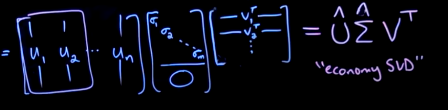

Because of this we can use an economy SVD instead.

m = 4;
n = 10;
X = randi(10, n, m);
[U, sigma, V] = svd(X, 'econ');
norm(U(:, 1)) % see how they are all unit vectors.

ans = 1.0000

disp(X)

     9    10     4     7
     1     1     1     6
     6     6     3     3
     7     2     1     2
     6     6    10     1
     5     7     1     4
     4     2     2     1
     7     8     1     7
    10     4     3     5
     7     9     1     4



disp(U)

   -0.4852    0.0815    0.1834   -0.0871
   -0.1220    0.2539    0.0009   -0.8303
   -0.2931   -0.0795    0.0575    0.1091
   -0.2092   -0.0057   -0.5678    0.1970
   -0.3277   -0.8434    0.2179   -0.1960
   -0.2873    0.1823    0.2439    0.1448
   -0.1458   -0.1338   -0.1923    0.0738
   -0.3830    0.3507    0.1169   -0.0991
   -0.3603   -0.0182   -0.6505   -0.0836
   -0.3639    0.1916    0.2447    0.4131



disp(U * sigma) % See how it isn't resized, just properly scaled.

  -15.6217    0.7424    1.0998   -0.4480
   -3.9282    2.3117    0.0055   -4.2691
   -9.4362   -0.7242    0.3446    0.5610
   -6.7365   -0.0516   -3.4045    1.0129
  -10.5502   -7.6793    1.3064   -1.0076
   -9.2495    1.6596    1.4622    0.7445
   -4.6949   -1.2184   -1.1530    0.3794
  -12.3309    3.1934    0.7010   -0.5097
  -11.6005   -0.1659   -3.9006   -0.4301
  -11.7172    1.7444    1.4672    2.1241



So another way to say it, is that matrix X is approximated by these products. Which at the end of the day is an addition of several rank 1 matrices.

With each addition, the approximatoin of X improves. Think about it, the last sigmas are really small, so they don't really change anything.

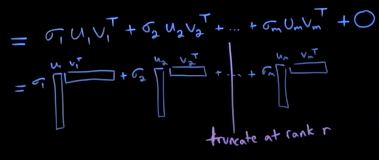

Defining r at some arbitrary sigma value when it becomes too small, then it is just a good approximation to the amount you requested.

#### Ways to calculate U and V

Check Lin alg notebook.

#### SVD example using r truncation

clear
BasicFace = imread('yamm.jpg');
Matrix = double(im2gray(BasicFace));
m = size(Matrix, 1), n = size(Matrix, 2);

m = 720

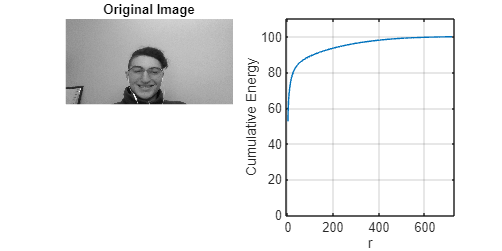

pixels_used = (m*n);

subplot(2, 2, 1)
imagesc(Matrix), axis off
colormap gray
title("Original Image");

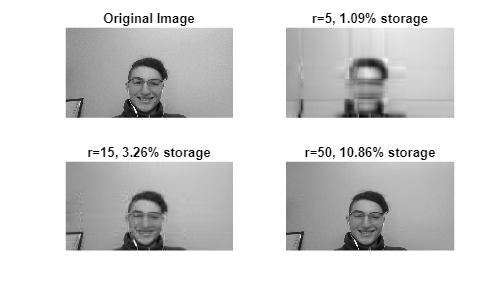


[U, S, V] = svd(Matrix, 'econ');

plot_index = 2;
for r=[5 15 50]  % Truncation value
    ImageApprox = U(:,1:r)*S(1:r,1:r)*V(:,1:r)'; % Approx. image
    subplot(2,2, plot_index);
    plot_index = plot_index + 1;
    imagesc(ImageApprox), axis off
    pixels_used_by_r = r*(m+n+1);
    title(['r=',num2str(r,'%d'),', ',num2str(100*pixels_used_by_r/pixels_used,'%2.2f'),'% storage']);
end
set(gcf,'Position',[0 0 n m])

Lets get into some of the compression: we use this formula for the percentage used:

- The total number of pixels in the original image is `width*height`.

- For a given value of `r` (the truncation value), we use the first `r` singular values to compute the compressed image.

- The number of singular values used is `r`, so the total number of values we need to store is `r*m + r*n + r` (the `r` at the end accounts for the `U`, `S`, and `V` matrices themselves).

- `U` is an `m`-by-`r` matrix, where `m` is the number of rows in the original matrix (i.e., the height of the image).

- `S` is an `r`-by-`r` diagonal matrix. (only r elements)

- `V` is a `n`-by-`r` matrix, where `n` is the number of columns in the original matrix (i.e., the width of the image).

To see exactly how much r you want to keep, you can check how important the later Rs are.

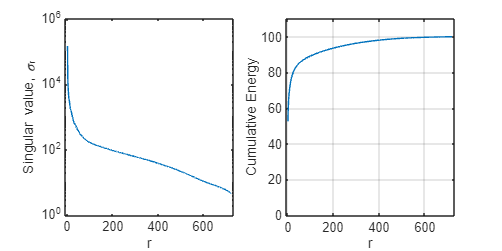

% See what the r values to every eigenvector
figure, subplot(1,2,1)
semilogy(diag(S)), grid off
xlabel('r')
ylabel('Singular value, \sigma_r')
xlim([-m/100 m+10])
subplot(1,2,2)

% Plot percentage of data in each consecutive r.
plot(cumsum(diag(S))/sum(diag(S)) * 100), grid on
xlabel('r')
ylabel('Cumulative Energy')
xlim([-m/100 m+10]); ylim([0 1.1 * 100])
set(gcf,'Position',[100 100 500 250])

### Face reconstruction

Going back to the eigenfaces example, what happens when you introduce a new face, how can you construct it using the set of eigenvectors.

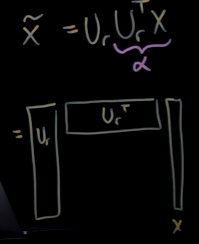

So what you do is given a vector image x, you can get the coefficients of our space Ur, by multiplying by the inverse the transpose, now its close to the inverse, not exact, because it is Ur. This gives us, how much of each element of U, x uses to construct itself. Then multiplying by Ur, of the given coefficients will select the correct elements of U again to construct x.

Look at what happens if you use different amount of U, ie. different r values.

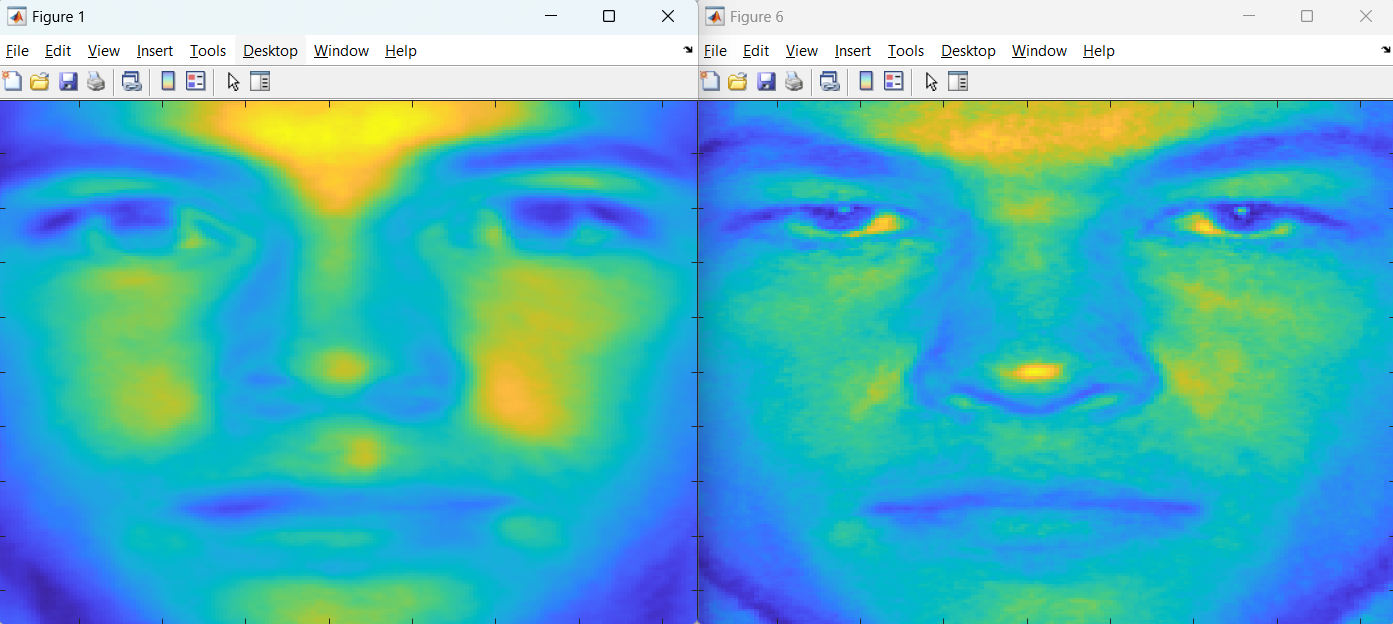

## Classification problem

### Alpha

For specific eigenfaces, many people will have different values. The alpha will be different, and categorized by a person. so you can classify different people.

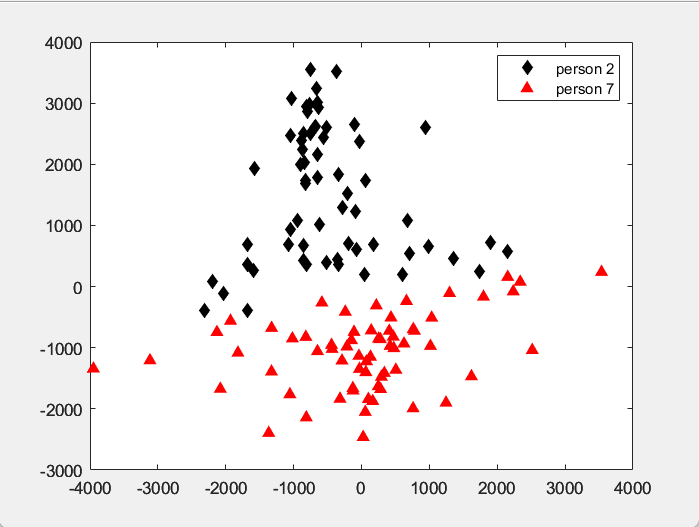

See, how the two different people are scattered in their weights for certain eigenfaces.